# REGALS analysis of CypA T-jump data

**The data were originally reported in:**

Thompson, M. C.; Barad, B. A.; Wolff, A. M.; Sun Cho, H.; Schotte, F.; Schwarz, D. M. C.; Anfinrud, P.; Fraser, J. S. *Temperature-Jump Solution X-Ray Scattering Reveals Distinct Motions in a Dynamic Enzyme.* Nature Chemistry 2019, 11 (11), 1058-1066. [https://doi.org/10.1038/s41557-019-0329-3](https://doi.org/10.1038/s41557-019-0329-3).

**The scattering profiles were downloaded from:** figshare on July 31, 2020. [https://doi.org/10.35092/yhjc.9177143](https://doi.org/10.35092/yhjc.9177143)

addpath('../matlab/'); % add REGALS code to path

## Load data

load data/CypA_Tjump.mat q I sigma delay_ns name
fprintf(1,'loaded dataset:\n');

loaded dataset:


fprintf(1,'  %s\n',name);

  CypA_wild_type/time_resolved/final_temp_29.9C



% get rid of the -10.1 us time point
I = I(:,2:end);
sigma = sigma(:,2:end);
delay_ns = delay_ns(2:end);

## Set up REGALS calculation

Each component has a concenetration and profile regularizer.

x = log10(delay_ns); % we'll seek smoothness vs logarithmic time

C1 = Component(...
    Concentration(x,'smooth',...
        'xmin',2.749,...
        'xmax',6.001,...
        'isZeroAtXmin',true,...
        'isZeroAtXmax',true,...
        'Nw',31),...
    Profile(q,'realspace','dmax',59,'Nw',101));

C2 = Component(...
    Concentration(x,'smooth',...
        'xmin',2.749,...
        'xmax',6.001,...
        'isZeroAtXmin',false,...
        'isZeroAtXmax',false,...
        'Nw',31),...
    Profile(q,'realspace','dmax',46,'Nw',101));

C3 = Component(...
    Concentration(x,'smooth',...
        'xmin',2.749,...
        'xmax',6.001,...
        'isZeroAtXmin',false,...
        'isZeroAtXmax',false,...
        'Nw',31),...
    Profile(q,'realspace','dmax',150,'Nw',101));

M = Mixture([C1,C2,C3]);

M.concentrationLambda = [1E1,1E1,1E1];
M.profileLambda = [1E11,1E11,1E11];

## Run REGALS

R = REGALS(I,sigma); % creat REGALS object

% set stopFun to return true when 400 iterations is exceeded
stopFun = @(iter,params) deal(iter >=  400,'maxIter');

updateFun = @(iter,NewMix,params,resid) ...
    fprintf(1,'%2d, x2 = %f, delta_profile = %s\n',...
    iter,params.x2,mat2str(params.delta_profile,3));

% run REGALS
[M1,params,resid] = R.run(M,stopFun,updateFun);

 1, x2 = 5.462713, delta_profile = [74 1.3e+03 282]
 2, x2 = 4.604198, delta_profile = [51.8 1.29e+03 282]
 3, x2 = 1.735921, delta_profile = [114 6.22 2.04]
 4, x2 = 1.768463, delta_profile = [7.36 1.3 1.05]
 5, x2 = 1.770279, delta_profile = [19.1 0.856 0.121]
 6, x2 = 1.747754, delta_profile = [3.39 0.303 0.0999]
 7, x2 = 1.738441, delta_profile = [9.3 0.286 0.136]
 8, x2 = 1.747515, delta_profile = [8.68 0.149 0.133]
 9, x2 = 1.759015, delta_profile = [3.89 0.361 0.182]
10, x2 = 1.762178, delta_profile = [5.88 0.395 0.229]
11, x2 = 1.762559, delta_profile = [12 0.195 0.249]
12, x2 = 1.774950, delta_profile = [44.8 0.311 0.302]
13, x2 = 1.802783, delta_profile = [25.8 0.715 0.384]
14, x2 = 1.817339, delta_profile = [94.1 0.471 0.217]
15, x2 = 1.795298, delta_profile = [17.2 0.187 0.04]
16, x2 = 1.778582, delta_profile = [173 0.19 0.0834]
17, x2 = 1.820958, delta_profile = [143 0.469 0.103]
18, x2 = 1.757129, delta_profile = [129 0.43 0.0694]
19, x2 = 1.801351, delta_profile = [131 0

## Extract results to plot

% P(r) functions
r1 = M1.Components(1).Profile.regularizer.w;
pr1 = [0;M1.uProfile{1};0];

r2 = M1.Components(2).Profile.regularizer.w;
pr2 = [0;M1.uProfile{2};0];

r3 = M1.Components(3).Profile.regularizer.w;
pr3 = [0;M1.uProfile{3};0];

% Particle components (extracted)
[I1,sigma1] = M1.extractProfile(I,sigma,1);
[I2,sigma2] = M1.extractProfile(I,sigma,2);
[I3,sigma3] = M1.extractProfile(I,sigma,3);

% Concentration components (extracted)
p1 = M1.extractConcentration(I,sigma,1);
p2 = M1.extractConcentration(I,sigma,2);
p3 = M1.extractConcentration(I,sigma,3);

% Regularized concentrations
x1 = M1.Components(1).Concentration.regularizer.w;
c1 = [0;M1.uConcentration{1};0];
x2 = M1.Components(2).Concentration.regularizer.w;
c2 = [M1.uConcentration{2}];
x3 = M1.Components(3).Concentration.regularizer.w;
c3 = [M1.uConcentration{3}];

## Plot the end results

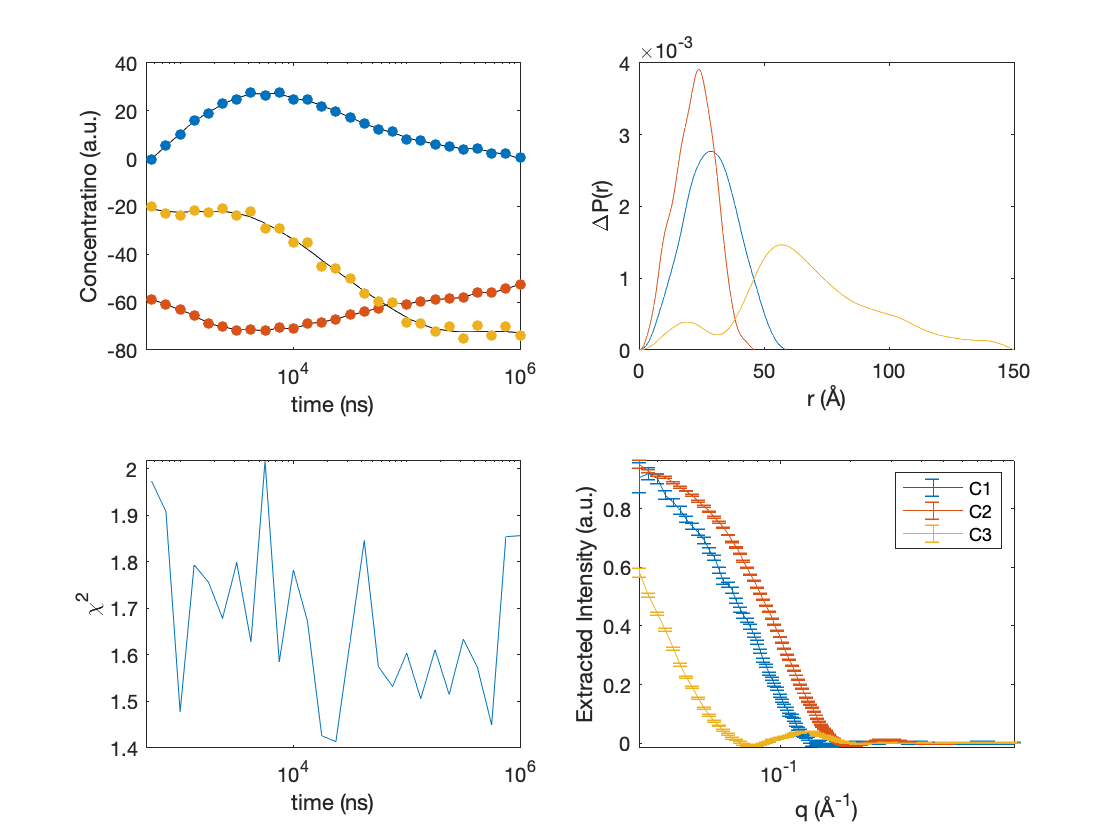

figure(1);clf;
subplot(2,2,1);
semilogx(10.^x1,c1,'k-',10.^x2,c2,'k-',10.^x2,c3,'k-');hold on;
scatter(10.^x,p1,30,'filled');hold on;
scatter(10.^x,p2,30,'filled');
scatter(10.^x,p3,30,'filled');
set(gca,'XLim',[500,1E6]);xlabel('time (ns)');ylabel('Concentratino (a.u.)');
subplot(2,2,3);
semilogx(10.^x,mean(resid.^2,1));
set(gca,'XLim',[500,1E6]);xlabel('time (ns)');ylabel('\chi^2');
subplot(2,2,2);
plot(r1,pr1,r2,pr2,r3,pr3);
xlabel('r (Å)');ylabel('\DeltaP(r)');
subplot(2,2,4);
errorbar(q,I1,sigma1,'DisplayName','C1');hold on;
errorbar(q,I2,sigma2,'DisplayName','C2');
errorbar(q,I3,sigma3,'DisplayName','C3');
set(gca,'XScale','Log','Yscale','Lin','Ylim',[-Inf,Inf],'Xlim',[-Inf,Inf]);
legend show; xlabel('q (Å^{-1})'); ylabel('Extracted Intensity (a.u.)');